clear; clc;
addpath 'C:\SharedDocs\GitHub\Math502B\MATLAB\mfuns'
mFile = '../mask2m_16_16.mat';
load(mFile); % mask2m 304x304x361

% Get the dimensions of the data
[h, w, c] = size(mask2m);


% Reshape the data into a 2D matrix
x = reshape(mask2m, h * w, c);



% Calculate the FFT 
fftx = fft(x, [], 2);
% Calculate normalized magnitude and angle
[mag, ang, frq] = freqMag(fftx);
% Calculate the Energy Spectrum of fftx
eSpec = mag.^2; 

## Significant Frequencies

bf = csvread('SigFrqs95zlim.csv');

### Extracting Energy based on the Significant Frequencies

SigFrqs = bf;
beSpec = eSpec(:, SigFrqs+1);


### Finding clusters by Significant-Freq Value

Elim = 4; % Energy level for significant frequencies
K = 6; % number of clusters
%distMathod = 'sqeuclidean'; % 61% & 61%
distMathod = 'cityblock'; % 61% & 59%
%distMathod = 'cosine'; % 61% & 61%
%distMathod = 'correlation'; % 61% & 61%
%distMathod = 'hamming'; % 61% & 61%

% Frequency Signature
beSig =  bin2dec(char(1.*(beSpec>Elim)+'0'));
beSigSig = beSpec>Elim;

[beSigClusters, beSigCenters, beSigWinSS] = kmeans(beSig, K,'Distance','cityblock', 'Display','final','Replicates',5);

Replicate 1, 1 iterations, total sum of distances = 245426.
Replicate 2, 2 iterations, total sum of distances = 1.17947e+06.
Replicate 3, 2 iterations, total sum of distances = 245426.
Replicate 4, 2 iterations, total sum of distances = 1.10971e+06.
Replicate 5, 2 iterations, total sum of distances = 245426.
Best total sum of distances = 245426


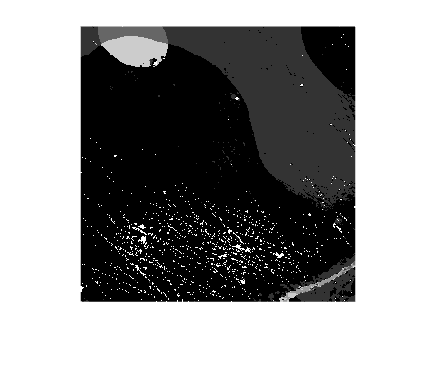

mat2img(reshape(beSigClusters, [h w]));

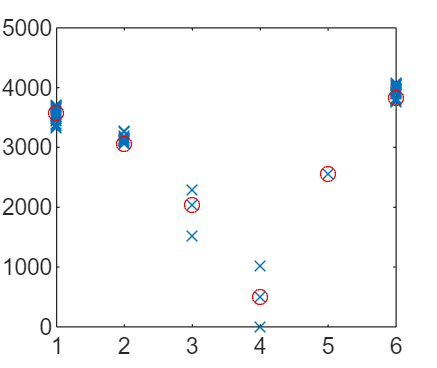


plot(beSigClusters, beSig, "x")
hold on
plot(beSigClusters, beSigCenters(beSigClusters), 'ro')
hold off


writematrix(beSigClusters, "FFT6Cluster_SigVal4Elim95zlim.csv")

#### Testing Significant-Freq Value Clusters

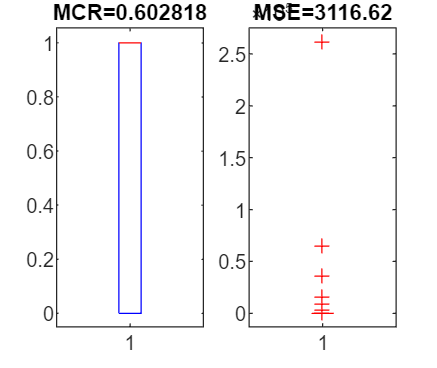


% Test
mseC = zeros(h*w, 1);
mse = zeros(h*w, 1);
mcr = zeros(h*w, 1);
k1s = ones([size(beSigCenters, 1) 1]);
for j=1:w*h
    [magj, ~, frqj] = freqMag(fft(x(j, :)));
    %sigFrqj = frqj(SigFrqs+1);
    %sigMagj = magj(sigFrqj+1);
    sigValj = bin2dec(char(1.*(magj(SigFrqs+1)>Elim)+'0'));
    ds = sum((beSigCenters-k1s*sigValj).^2, 2);
    [m, i] = min(ds);
    mseC(j) = m;
    mcr(j) = 1-(i==beSigClusters(j));
end
subplot(1,2,1)
boxplot(mcr)
title(sprintf("MCR=%4g", mean(mcr)))
subplot(1,2,2)
boxplot(mseC)
title(sprintf("MSE=%4g", mean(mseC)))

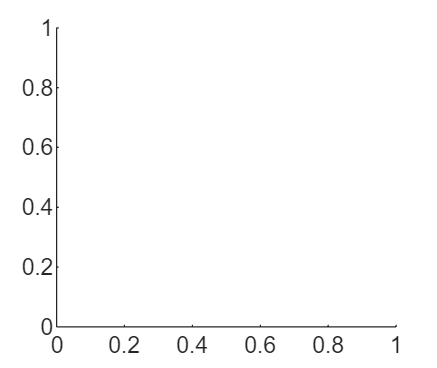

subplot(1,1,1)

### Finding clusters by Significant-Freq Signature

[beSigSigClusters, beSigSigCenters, beSigSigWinSS] = kmeans(beSigSig, K,'Distance','cityblock', 'Display','final','Replicates',5);

Replicate 1, 2 iterations, total sum of distances = 3901.
Replicate 2, 4 iterations, total sum of distances = 2963.
Replicate 3, 1 iterations, total sum of distances = 2044.
Replicate 4, 1 iterations, total sum of distances = 2839.
Replicate 5, 1 iterations, total sum of distances = 2419.
Best total sum of distances = 2044


mat2img(reshape(beSigClusters, [h w]));

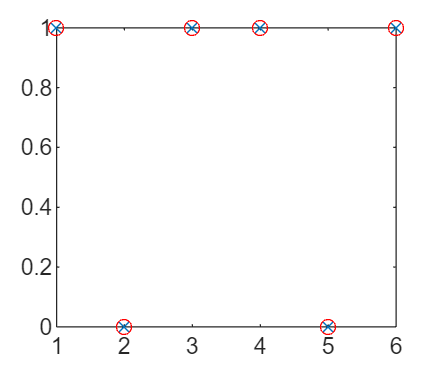


dm = 3;
plot(beSigSigClusters, beSigSig(:,dm), "x")
hold on
plot(beSigSigClusters, beSigSigCenters(beSigSigClusters, dm), 'ro')
hold off


writematrix(beSigSigClusters, "FFT6Cluster_SigSig4Elim95zlim.csv")

#### Testing Significant-Freq Signature Clusters

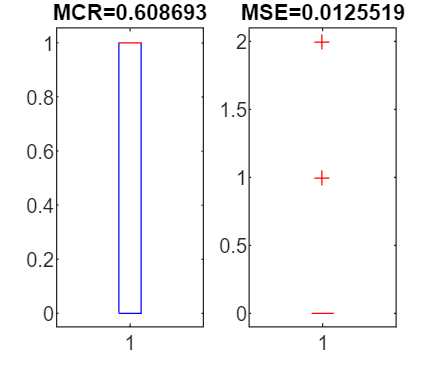


% Test
mseC = zeros(h*w, 1);
mse = zeros(h*w, 1);
mcr = zeros(h*w, 1);
k1s = ones([size(beSigSigCenters, 1) 1]);
for j=1:w*h
    [magj, ~, frqj] = freqMag(fft(x(j, :)));
    %sigFrqj = frqj(SigFrqs+1);
    %sigMagj = magj(sigFrqj+1);
    sigSigj = magj(SigFrqs+1)>Elim;
    ds = sum((beSigSigCenters-k1s*sigSigj).^2, 2);
    [m, i] = min(ds);
    mseC(j) = m;
    mcr(j) = 1-(i==beSigSigClusters(j));
end
subplot(1,2,1)
boxplot(mcr)
title(sprintf("MCR=%4g", mean(mcr)))
subplot(1,2,2)
boxplot(mseC)
title(sprintf("MSE=%4g", mean(mseC)))

subplot(1,1,1)